# Assignment Intelligent Systems

Gabriela Moreno Boriero

w22070617

## Reading Dataset

% cleaning the space to start
clc;
clear;
%reading dataset
data = readtable('fetal_health.csv')

data = 2126×22 table
    baselineValue    accelerations    fetal_movement    uterine_contractions    light_decelerations    severe_decelerations    prolongued_decelerations    abnormal_short_term_variability    mean_value_of_short_term_variability    percentage_of_time_with_abnormal_long_term_variability    mean_value_of_long_term_variability    histogram_width    histogram_min    histogram_max    histogram_number_of_peaks    histogram_number_of_zeroes    histogram_mode    histogram_mean    histogram_median    histogram_variance    histogram_tendency    fetal_health
    _____________    _______

## Overview of the data

summary(data)

Variables:

    baselineValue: 2126×1 double

        Properties:
            Description:  baseline value
        Values:

            Min         106   
            Median      133   
            Max         160   

    accelerations: 2126×1 double

        Properties:
            Description:  accelerations
        Values:

            Min            0  
            Median     0.002  
            Max        0.019  

    fetal_movement: 2126×1 double

        Properties:
            Description:  fetal_movement
        Values:

            Min            0  
            Median         0  
            Max        0.481  

    uterine_contractions: 2126×1 double

        Properties:
            Description:  uterine_contractions
        Values:

            Min            0  
            Median     0.004  
            Max        0.015  

    light_decelerations: 2126×1 double

        Properties:
      

## Seperate data in training and test

% Cross varidation (train: 70%, test: 30%)
cv = cvpartition(size(data,1),'HoldOut',0.3);
idx = cv.test;

% Separate to training and test data
dataTrain = data(~idx,:);
dataTest  = data(idx,:);

%seperate in target and features the training data
xdataTrain = dataTrain(:,1:end-1); %features
YdataTrain = dataTrain(:,end);     %target

%seperate in target and features the testing data
xdataTest = dataTest(:,1:end-1);   %features
YdataTest = dataTest(:,end);       %target

## **Linear Discriminant Analysis**

reference: [https://uk.mathworks.com/help/stats/classification-example.html](https://uk.mathworks.com/help/stats/classification-example.html) 

%Train a discriminant analysis model using the entire data set.
lda = fitcdiscr(xdataTrain,YdataTrain);
%Predict the training sample labels.
ldaClass = resubPredict(lda);

%The observations with known class labels are usually called the training data. Now compute the resubstitution error, which is the misclassification error (the proportion of misclassified observations) on the training set.
ldaResubErr = resubLoss(lda)

ldaResubErr = 0.1222


% Predicting results
ypred = predict(lda,xdataTest);

% Checking results
figure
cm=confusionchart(YdataTest{:,:},ypred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


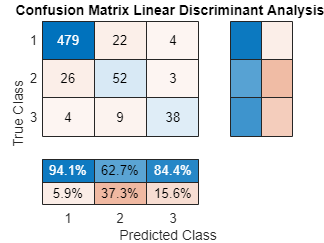

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = ' Confusion Matrix Linear Discriminant Analysis';

[m,order]=confusionmat(YdataTest{:,:},ypred);
Diagonal=diag(m);
sum_rows=sum(m,2);
Precision=Diagonal./sum_rows;
Overall_Precision=mean(Precision)

Overall_Precision = 0.7785

sum_col=sum(m,1);
recall=Diagonal./sum_col';
overall_recall=mean(recall)

overall_recall = 0.8040

F1_Score=2*((Overall_Precision*overall_recall)/(Overall_Precision+overall_recall))

F1_Score = 0.7911

## Using Decision Tree Classifier

reference: workshop 2

% build a decision tree classifier using the training set
mdl_ctree = fitctree(xdataTrain,YdataTrain);

% test the trained decision tree using the testing set
ypred = predict(mdl_ctree,xdataTest);


% Checking results
figure
cm=confusionchart(YdataTest{:,:},ypred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


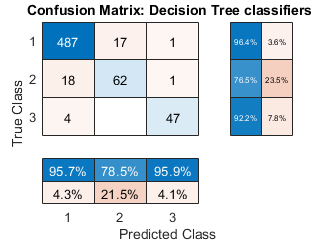

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = ' Confusion Matrix: Decision Tree classifiers';

[m,order]=confusionmat(YdataTest{:,:},ypred);
Diagonal=diag(m);
sum_rows=sum(m,2);
Precision=Diagonal./sum_rows;
Overall_Precision=mean(Precision)

Overall_Precision = 0.8838

sum_col=sum(m,1);
recall=Diagonal./sum_col';
overall_recall=mean(recall)

overall_recall = 0.9003

F1_Score=2*((Overall_Precision*overall_recall)/(Overall_Precision+overall_recall))

F1_Score = 0.8919

## TreeBagger

reference: https://www.mathworks.com/help/stats/treebagger.html

%Train an ensemble of bagged classification trees using the entire data set. Specify 50 weak learners. Store the out-of-bag observations for each tree. By default, TreeBagger grows deep trees.
Mdl = TreeBagger(50,xdataTrain,YdataTrain,...
    Method="classification",...
    OOBPrediction="on")

Mdl =   TreeBagger
Ensemble with 50 bagged decision trees:
                    Training X:            [1489x21]
                    Training Y:             [1489x1]
                        Method:       classification
                 NumPredictors:                   21
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'

  Properties, Methods


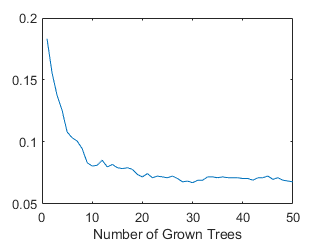


%The Mdl.Trees property is a 50-by-1 cell vector that contains the trained classification trees for the ensemble. Each tree is a CompactClassificationTree object. View the graphical display of the first trained classification tree.
view(Mdl.Trees{1},Mode="graph")

%Plot the out-of-bag classification error over the number of grown classification trees.
plot(oobError(Mdl))
xlabel("Number of Grown Trees")



%Predict labels for out-of-bag observations. Display the results for a random set of 10 observations.

oobLabels = oobPredict(Mdl);
ind = randsample(length(oobLabels),10);
table(YdataTrain{:,:},oobLabels,...
    VariableNames=["TrueLabel" "PredictedLabel"])

ans = 1489×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        2            {'3'}     
        1            {'1'}     
        1            {'1'}     
        1            {'1'}     
        1            {'1'}     
        3            {'3'}     
        3            {'3'}     
        3            {'3'}     
        3            {'3'}     
        2            {'2'}     
        2            {'2'}     
        1            {'1'}     
        1            {'1'}     
        2            {'1'}     
        1            {'1'}     
        1            {'1'}     


ypred = predict(Mdl,xdataTest);

% Checking results
figure
cm=confusionchart(YdataTest{:,:},str2double(ypred))

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


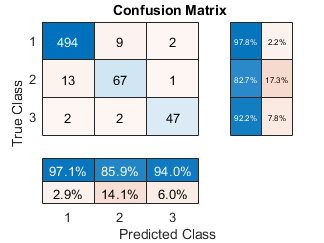

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = ' Confusion Matrix';

[m,order]=confusionmat(YdataTest{:,:},str2double(ypred));
Diagonal=diag(m);
sum_rows=sum(m,2);
Precision=Diagonal./sum_rows;
Overall_Precision=mean(Precision)

Overall_Precision = 0.9090

sum_col=sum(m,1);
recall=Diagonal./sum_col';
overall_recall=mean(recall)

overall_recall = 0.9232

F1_Score=2*((Overall_Precision*overall_recall)/(Overall_Precision+overall_recall))

F1_Score = 0.9160

## References

### Separate in Test and Training

https://uk.mathworks.com/matlabcentral/answers/377839-split-training-data-and-testing-data

### Checking results

https://www.mathworks.com/matlabcentral/answers/689494-how-to-calculate-confusion-matrix-accuracy-and-precision